### 一.  D-H法则构建连杆

clc
clear
close all

% 一个回转关节和一个移动关节组成的平面极坐标机器人
% 实际齐次坐标变换阵中：theta/d = jointvariable + ofsset
% d        theta               a           alpha           offset 
d1 = 1.2;  theta1 = 0.0;      a1 = 0.2;   alpha1 = pi/2;   ofs1 = 0;
d2 = 0.0;  theta2 = 0.0;      a2 = 0.6;   alpha2 = pi/2;   ofs2 = 0;

% 生成连杆1，2
L1 = Link('d', d1, 'a', a1, 'alpha', alpha1, 'offset', ofs1, 'revolute')

 
L1 = 
Revolute(std): theta=q, d=1.2, a=0.2, alpha=1.5708, offset=0


L2 = Link('prismatic', 'theta', theta2, 'a', a2, 'alpha', alpha2, 'offset', ofs2, 'qlim',[0.5,2])

 
L2 = 
Prismatic(std): theta=0, d=q, a=0.6, alpha=1.5708, offset=0



% 生成机器人
bot = SerialLink([L1 L2], 'name', 'my robot')

 
bot = 
 
my robot:: 2 axis, RP, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        1.2|        0.2|     1.5708|          0|
|  2|          0|         q2|        0.6|     1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


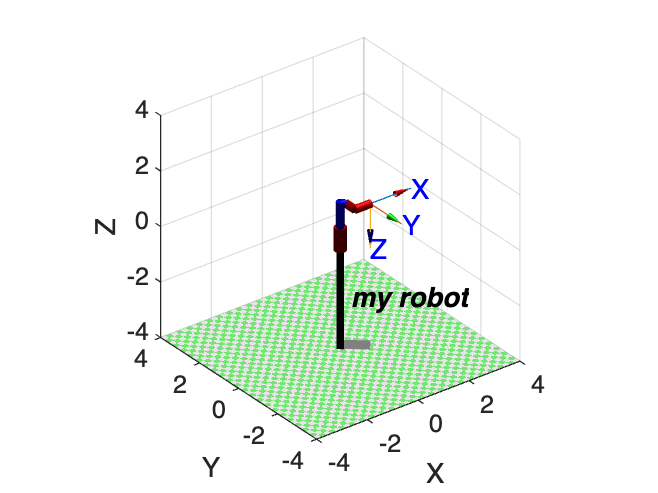


% 用Fkine求正运动学，即获得坐标变换矩阵
qz = [0, 0.5];
qs = [pi/3, 1.5];
bot.plot(qz);       %显示qz位姿的机器人

T = bot.fkine(qs)   %显示末端坐标系的T阵

 

T = 
    0.5000    0.8660         0     1.699
    0.8660   -0.5000         0  -0.05718
         0         0        -1       1.2
         0         0         0         1



% 根据D-H法则，手动计算的坐标变换矩阵
theta1 = qs(1); d2 = qs(2);
T01A = transl(0,0,d1)*trotz(theta1);
T01B = transl(a1,0,0)*trotx(alpha1);
T01 = T01A * T01B

T01 =     0.5000         0    0.8660    0.1000
    0.8660         0   -0.5000    0.1732
         0    1.0000         0    1.2000
         0         0         0    1.0000



T12A = transl(0,0,d2)*trotz(theta2);
T12B = transl(a2,0,0)*trotx(alpha2);
T02 = T01A*T12A

T02 =     0.5000   -0.8660         0         0
    0.8660    0.5000         0         0
         0         0    1.0000    2.7000
         0         0         0    1.0000


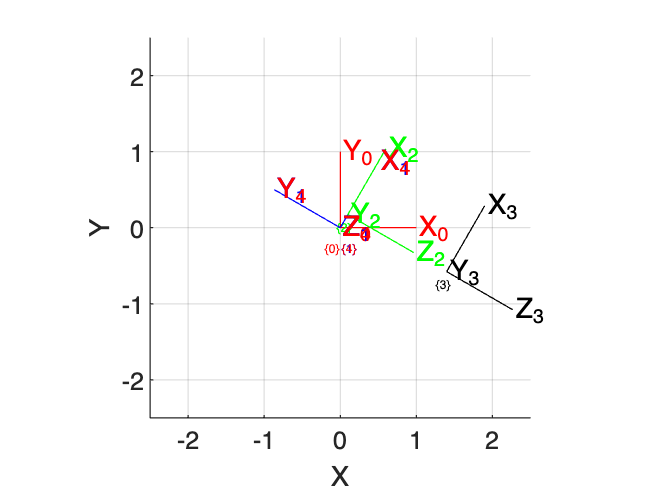

% T和T02是一致的。

% 示意D-H法则的坐标变化过程
T0 = transl(0,0,0); 
plotvol([-2.50 2.5 -2.5 2.5 -2.5 2.5]);
trplot(T0, 'frame', '0', 'color', 'r');
trplot(T01A, 'frame', '1', 'color', 'b');
trplot(T01, 'frame', '2', 'color', 'g');
trplot(T01*T12A, 'frame', '3', 'color', 'k');
trplot(T02, 'frame', '4', 'color', 'r');

### 二. D-H法则构建PUMA560

close all
% 角度换算
deg = pi/180;

% Revolute命令构建运动学及动力学参数
L(1) = Revolute('d', 0, 'a', 0, 'alpha', pi/2, ...
    'I', [0, 0.35, 0, 0, 0, 0], ...
    'r', [0, 0, 0], ...
    'm', 0, ...
    'Jm', 200e-6, ...
    'G', -62.6111, ...
    'B', 1.48e-3, ...
    'Tc', [0.395 -0.435], ...
    'qlim', [-160 160]*deg );

L(2) = Revolute('d', 0, 'a', 0.4318, 'alpha', 0, ...
    'I', [0.13, 0.524, 0.539, 0, 0, 0], ...
    'r', [-0.3638, 0.006, 0.2275], ...
    'm', 17.4, ...
    'Jm', 200e-6, ...
    'G', 107.815, ...
    'B', .817e-3, ...
    'Tc', [0.126 -0.071], ...
    'qlim', [-45 225]*deg );

L(3) = Revolute('d', 0.15005, 'a', 0.0203, 'alpha', -pi/2,  ...
    'I', [0.066, 0.086, 0.0125, 0, 0, 0], ...
    'r', [-0.0203, -0.0141, 0.070], ...
    'm', 4.8, ...
    'Jm', 200e-6, ...
    'G', -53.7063, ...
    'B', 1.38e-3, ...
    'Tc', [0.132, -0.105], ...
    'qlim', [-225 45]*deg );

L(4) = Revolute('d', 0.4318, 'a', 0, 'alpha', pi/2,  ...
    'I', [1.8e-3, 1.3e-3, 1.8e-3, 0, 0, 0], ...
    'r', [0, 0.019, 0], ...
    'm', 0.82, ...
    'Jm', 33e-6, ...
    'G', 76.0364, ...
    'B', 71.2e-6, ...
    'Tc', [11.2e-3, -16.9e-3], ...
    'qlim', [-110 170]*deg);

L(5) = Revolute('d', 0, 'a', 0, 'alpha', -pi/2,  ...
    'I', [0.3e-3, 0.4e-3, 0.3e-3, 0, 0, 0], ...
    'r', [0, 0, 0], ...
    'm', 0.34, ...
    'Jm', 33e-6, ...
    'G', 71.923, ...
    'B', 82.6e-6, ...
    'Tc', [9.26e-3, -14.5e-3], ...
    'qlim', [-100 100]*deg );


L(6) = Revolute('d', 0, 'a', 0, 'alpha', 0,  ...
    'I', [0.15e-3, 0.15e-3, 0.04e-3, 0, 0, 0], ...
    'r', [0, 0, 0.032], ...
    'm', 0.09, ...
    'Jm', 33e-6, ...
    'G', 76.686, ...
    'B', 36.7e-6, ...
    'Tc', [3.96e-3, -10.5e-3], ...
    'qlim', [-266 266]*deg );

% 构建PUMA560机器人
puma560_1 = SerialLink(L, 'name', 'Puma 560-1', ...
    'manufacturer', 'Unimation', 'ikine', 'puma', 'comment', 'viscous friction; params of 8/95');

% 指定显示模型
puma560_1.display()

 
puma560_1 = 
 
Puma 560-1 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE          
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


%
% 典型位置姿变量
%
qz = [0 0 0 0 0 0];         % zero angles, L shaped pose
qr = [0 pi/2 -pi/2 0 0 0];  % ready pose, arm up
qs = [0 0 -pi/2 0 0 0];     % initial pose
qn = [0 pi/4 pi 0 pi/4  0];

% 正运动学求T矩阵
q = qz;
puma560_1.plot(q); T = puma560_1.fkine(q)

 

T = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1    0.4318
         0         0         0         1


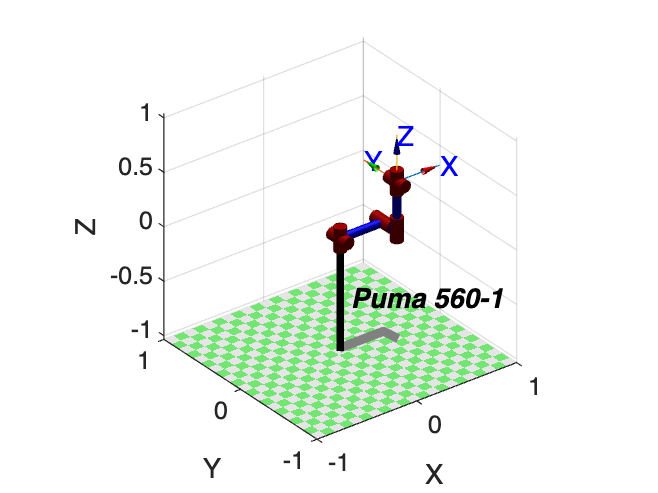

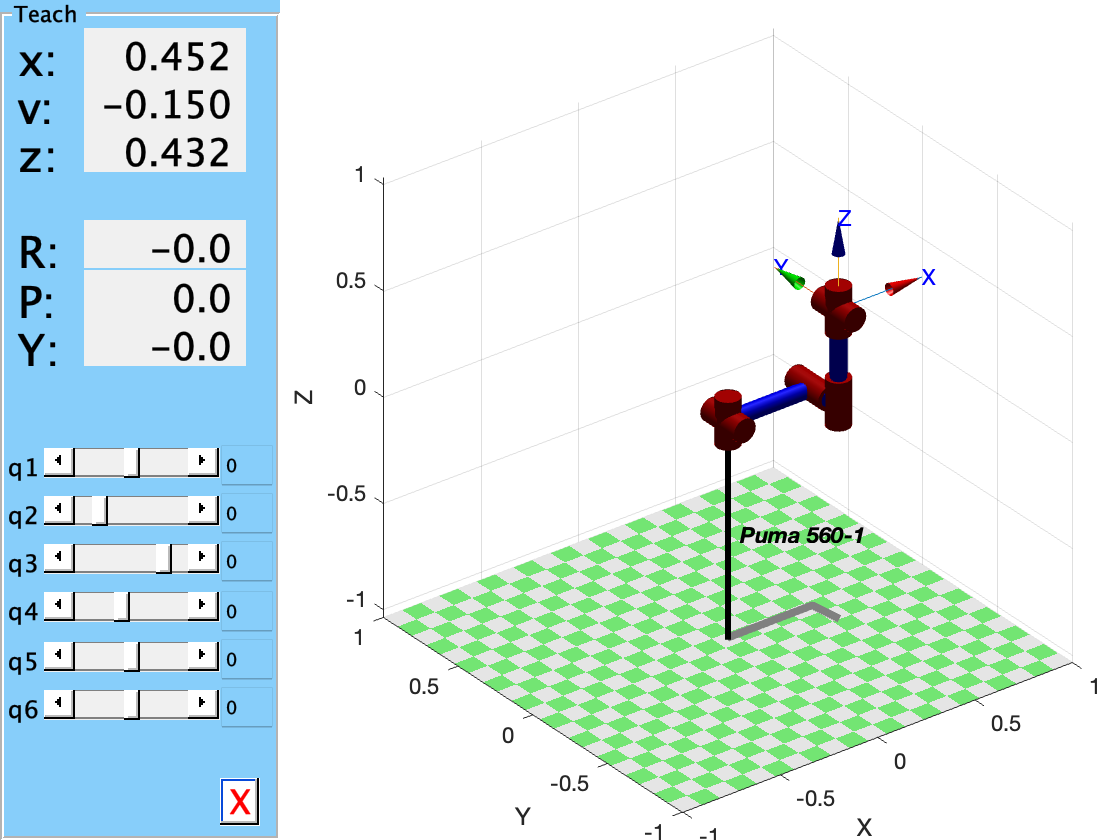

figure;puma560_1.teach()

### 三. 另一位形的D-H法则构建PUMA560

由于 $q_3$的零位选择不同，$Z_3$的方向可能相反，就会有不同的D-H定义，例如下面的例子：

因此，已经注意每个坐标系和关节角度零位的定义。

% 角度换算
deg = pi/180;

L(1) = Revolute('d', 0, 'a', 0, 'alpha', pi/2, ...
    'I', [0, 0.35, 0, 0, 0, 0], ...
    'r', [0, 0, 0], ...
    'm', 0, ...
    'Jm', 200e-6, ...
    'G', -62.6111, ...
    'B', 1.48e-3, ...
    'Tc', [0.395 -0.435], ...
    'qlim', [-160 160]*deg );

L(2) = Revolute('d', 0, 'a', 0.4318, 'alpha', 0, ...
    'I', [0.13, 0.524, 0.539, 0, 0, 0], ...
    'r', [-0.3638, 0.006, 0.2275], ...
    'm', 17.4, ...
    'Jm', 200e-6, ...
    'G', 107.815, ...
    'B', .817e-3, ...
    'Tc', [0.126 -0.071], ...
    'qlim', [-45 225]*deg );

L(3) = Revolute('d', 0.15005, 'a', 0.0203, 'alpha', pi/2,  ...
    'I', [0.066, 0.086, 0.0125, 0, 0, 0], ...
    'r', [-0.0203, -0.0141, 0.070], ...
    'm', 4.8, ...
    'Jm', 200e-6, ...
    'G', -53.7063, ...
    'B', 1.38e-3, ...
    'Tc', [0.132, -0.105], ...
    'qlim', [-225 45]*deg );

L(4) = Revolute('d', 0.4318, 'a', 0, 'alpha', -pi/2,  ...
    'I', [1.8e-3, 1.3e-3, 1.8e-3, 0, 0, 0], ...
    'r', [0, 0.019, 0], ...
    'm', 0.82, ...
    'Jm', 33e-6, ...
    'G', 76.0364, ...
    'B', 71.2e-6, ...
    'Tc', [11.2e-3, -16.9e-3], ...
    'qlim', [-110 170]*deg);

L(5) = Revolute('d', 0, 'a', 0, 'alpha', pi/2,  ...
    'I', [0.3e-3, 0.4e-3, 0.3e-3, 0, 0, 0], ...
    'r', [0, 0, 0], ...
    'm', 0.34, ...
    'Jm', 33e-6, ...
    'G', 71.923, ...
    'B', 82.6e-6, ...
    'Tc', [9.26e-3, -14.5e-3], ...
    'qlim', [-100 100]*deg );


L(6) = Revolute('d', 0, 'a', 0, 'alpha', 0,  ...
    'I', [0.15e-3, 0.15e-3, 0.04e-3, 0, 0, 0], ...
    'r', [0, 0, 0.032], ...
    'm', 0.09, ...
    'Jm', 33e-6, ...
    'G', 76.686, ...
    'B', 36.7e-6, ...
    'Tc', [3.96e-3, -10.5e-3], ...
    'qlim', [-266 266]*deg );

puma560_2 = SerialLink(L, 'name', 'Puma 560-2', ...
    'manufacturer', 'Unimation', 'ikine', 'puma', 'comment', 'viscous friction; params of 8/95');

% 指定显示模型
puma560_2.display()

 
puma560_2 = 
 
Puma 560-2 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE          
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|     1.5708|          0|
|  4|         q4|     0.4318|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


puma560_1.display()

 
puma560_1 = 
 
Puma 560-1 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE          
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



q = qz; q(3)=pi/2;
puma560_2.plot(q); T = puma560_2.fkine(q)

 

T = 
         0         0         1    0.8636
         0        -1         0   -0.1501
         1         0         0    0.0203
         0         0         0         1


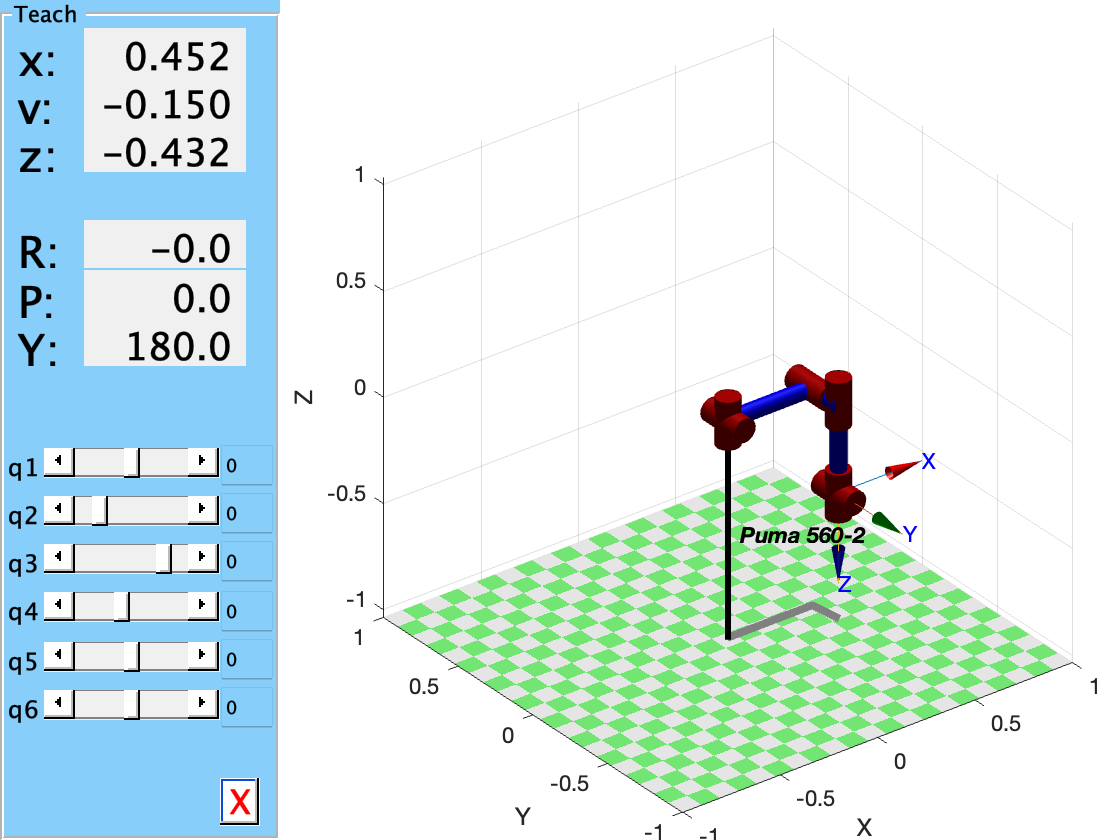

puma560_2.teach()

### 四. 逆运动学求解

Robotics ToolBox内嵌了Puma560的模型和逆运动学求解，同学们可以参照其求解的公式：https://github.com/petercorke/robotics-toolbox-matlab/blob/master/Octave/%40SerialLink/ikine6s.m

mdl_puma560                 
% create the model
% forward kinematics of a known set of joing angles
p560

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


T = p560.fkine(qn)

 

T = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1



% inverse kinematics - right handed, elbow up
qn_r1 = p560.ikine6s(T,'ru')

qn_r1 =    -0.0000    0.7854    3.1416   -0.0000    0.7854    0.0000



% 也可以这样(注意这里用的是右侧下肘的位形)：
qn_r2 = ikine6s(p560,T,'rd')

qn_r2 =    -0.0000   -0.8335    0.0940   -3.1416    0.8312    3.1416



% default IK
qn_r3 = p560.ikine(T)

qn_r3 =    -0.0000   -0.8335    0.0940    0.0000   -0.8312   -0.0000


%mask = [1 1 1 1 1 1];
%qn_r3 = p560.ikine(T,'mask',mask)

### **五。 速度运动学**

qz = [0 0 0 0 0 0];         % zero angles, L shaped pose
qr = [0 pi/2 -pi/2 0 0 0];  % ready pose, arm up
qs = [0 0 -pi/2 0 0 0];     % initial pose
qn = [0 pi/4 pi 0 pi/4  0]; % 

% This Jacobian is often referred to as the geometric Jacobian.
Jz = p560.jacobe(qz)

Jz =     0.1500   -0.4318   -0.4318         0         0         0
    0.4521    0.0000    0.0000         0         0         0
         0    0.4521    0.0203         0         0         0
         0         0         0         0         0         0
         0   -1.0000   -1.0000         0   -1.0000         0
    1.0000    0.0000    0.0000    1.0000    0.0000    1.0000



% This Jacobian is often referred to as the geometric Jacobian.
Jn = p560.jacobe(qn)

Jn =    -0.0000   -0.5963   -0.2910         0         0         0
    0.5963    0.0000    0.0000         0         0         0
    0.1500    0.0144    0.3197         0         0         0
   -1.0000         0         0    0.7071         0         0
   -0.0000   -1.0000   -1.0000   -0.0000   -1.0000         0
   -0.0000    0.0000    0.0000    0.7071    0.0000    1.0000



% 'trans'   Return translational submatrix of Jacobian
Jn_t = p560.jacobe(qn,'trans' )

Jn_t =    -0.0000   -0.5963   -0.2910         0         0         0
    0.5963    0.0000    0.0000         0         0         0
    0.1500    0.0144    0.3197         0         0         0



% 'rot'     Return rotational submatrix of Jacobian 
Jn_r = p560.jacobe(qn,'rot' )

Jn_r =    -1.0000         0         0    0.7071         0         0
   -0.0000   -1.0000   -1.0000   -0.0000   -1.0000         0
   -0.0000    0.0000    0.0000    0.7071    0.0000    1.0000
